close all;
clc;

# Q1

t = 0:0.01:100;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = ((1-s)*exp(-s))/((12*s+1)*(3*s+1)*(0.2*s + 1)*(0.05*s+1))

G =
 
                                 -s + 1
  exp(-1*s) * ---------------------------------------------
              0.36 s^4 + 9.15 s^3 + 39.76 s^2 + 15.25 s + 1
 
Continuous-time transfer function.



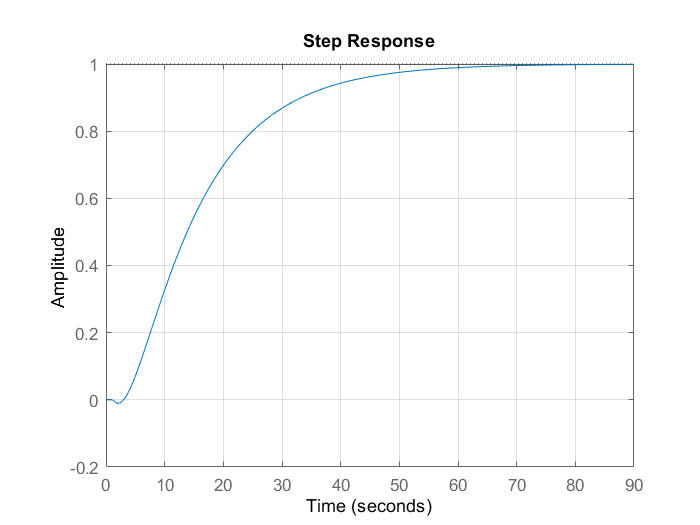

[y,~] = step(G,t);
step(G)
grid

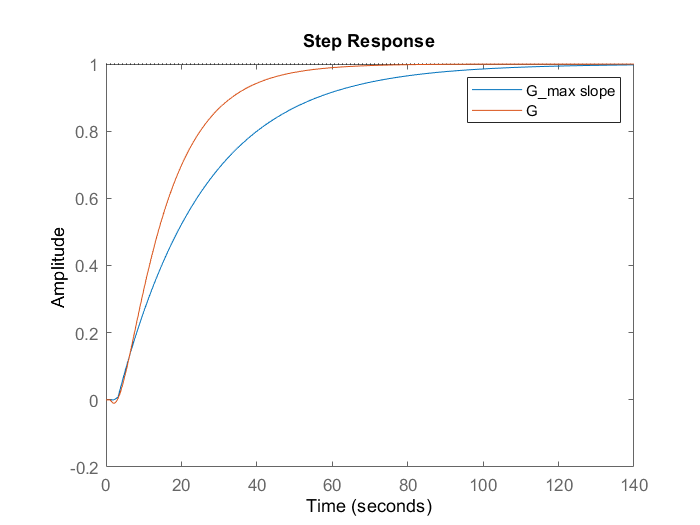

g1 = exp(-3*s)/(23*s+1);
[y1,~] = step(g1,t);
step(g1,G)
legend("G_{max slope}","G")

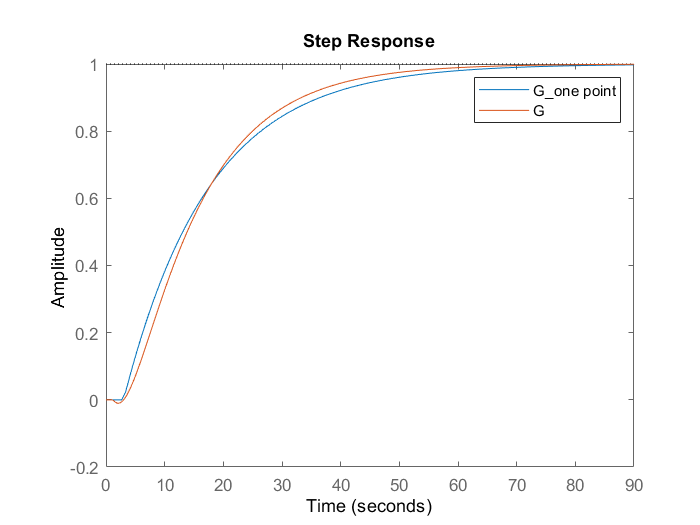


g2 = exp(-3*s)/(14.53*s+1) ;
[y2,~] = step(g2,t);
step(g2,G)
legend("G_{one point}","G")

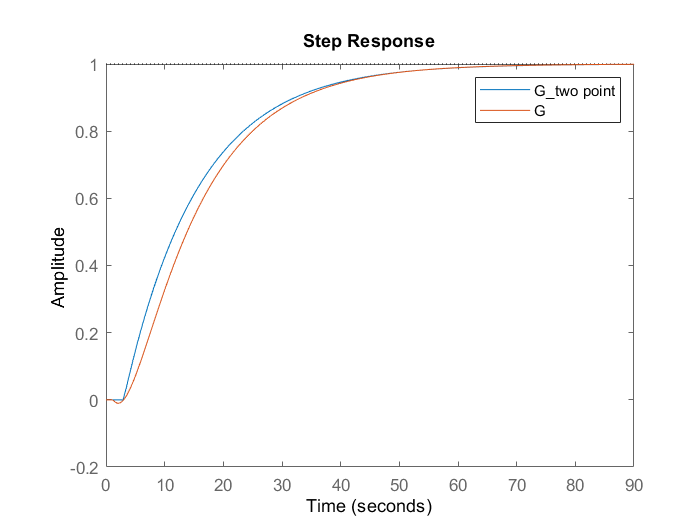


g3 = exp(-3*s)/(12.675*s+1) ;
[y3,~] = step(g3,t);
step(g3,G)
legend("G_{two point}","G")

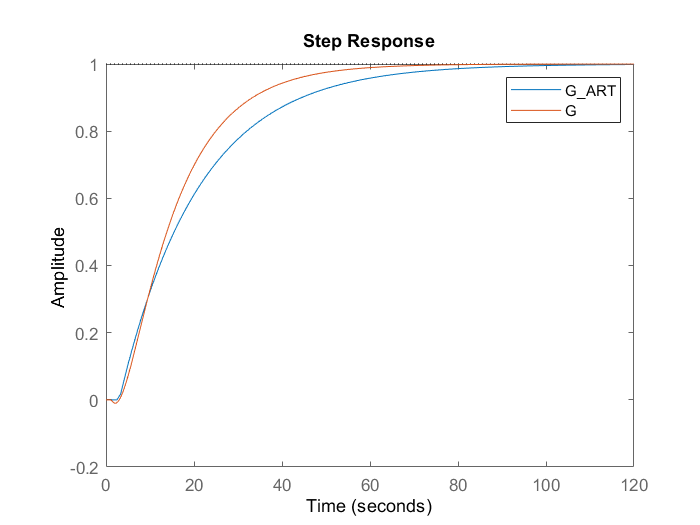


g4 = exp(-3*s)/(18*s+1) ;
[y4,~] = step(g4,t);
step(g4,G)
legend("G_{ART}","G")

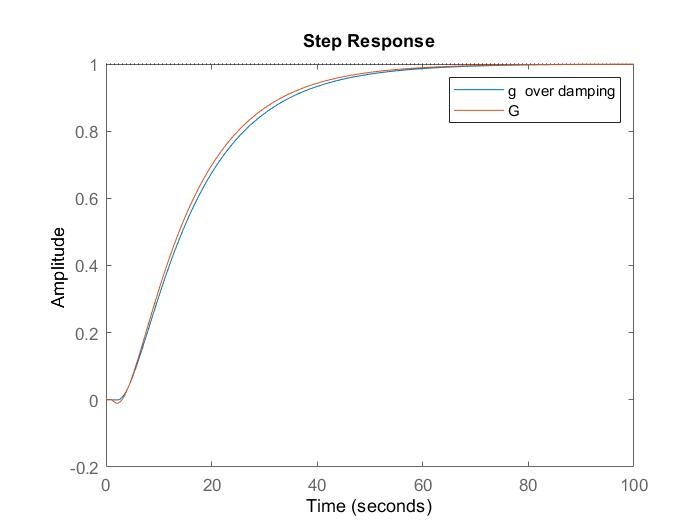

g5 = exp(-2.25*s)/((3.15*s+1)*(12.6*s+1)) ;
[y5,~] = step(g5,t);
step(g5,G)
legend("g  over damping","G")

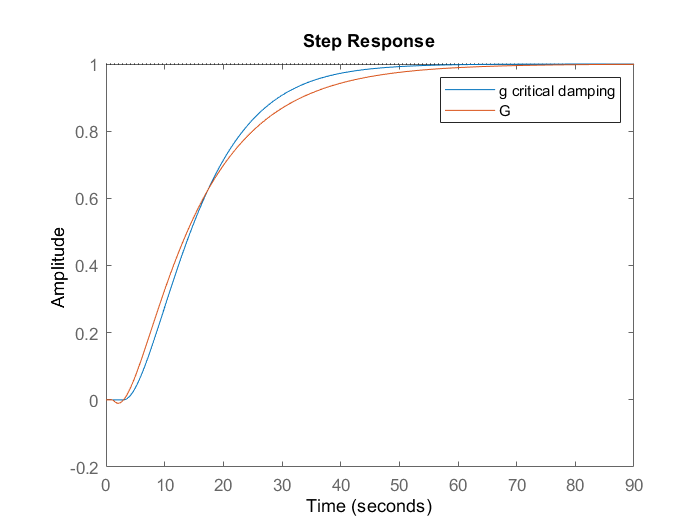



g6 = exp(-3*s)/((6.785*s+1)^2 );
[y6,~] = step(g6,t);
step(g6,G)
legend("g critical damping","G")

err_max_slope = mse(t.',y,y1)

err_max_slope = 0.0108

err_one_point = mse(t.',y,y2)

err_one_point = 4.6163e-04

err_two_point = mse(t.',y,y3)

err_two_point = 0.0011

err_ART = mse(t.',y,y4)

err_ART = 0.0026

err_over_damping = mse(t.',y,y5)

err_over_damping = 1.2575e-04

err_critical_damping = mse(t.',y,y6)

err_critical_damping = 5.1660e-04